clear
close all
clc
delete(gcp('nocreate'))
tic


## load data and functions


DIR ='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/';
spec='Results_dock_time/Initial_vel_fluid/';
loadDIR=[DIR spec];

% Declare constants, load functions and data
Const = Constants;
fDIR=[DIR 'Functions/'];
addpath(fDIR)
load([loadDIR 'Dock_time_eps_00001_inorbit_katy.mat'])

saveDIR=[DIR,'Results_dock_approx/Rdot_gauss_approx/'];
savename='rdot_gauss_param.mat';

## choose plot parameters

fsize=16;
width=20;
height=25;
options=optimset('MaxFunEvals',100000000);

## data manipulation

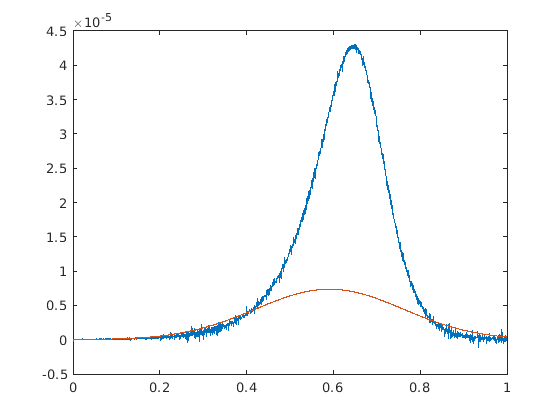

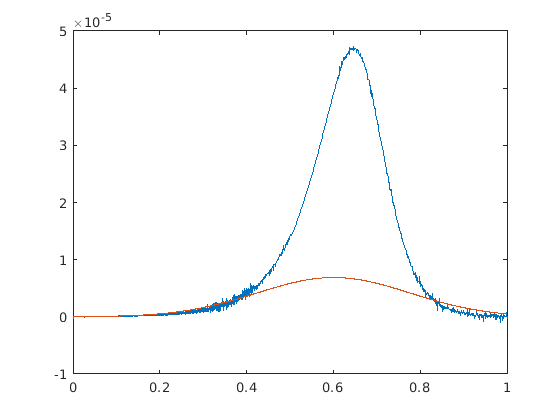

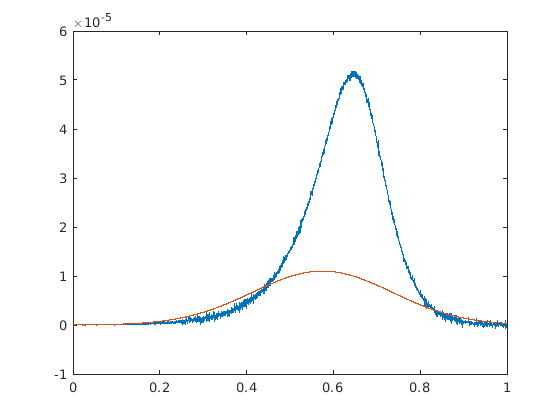


% choose relevant St/A values (for respective docking process)
wybor=[];
param=zeros(1,numel(part));
for p=1:numel(part)
    param(p)=part(p).par.A^(-1)*part(p).par.St;
    if imag(texit(p))==0 && ~isnan(texit(p))
        wybor=[wybor,p];
    end
end

param_wyb=param(wybor);
parmin=min(param_wyb);
parmax=max(param_wyb);
St_wyb=St(wybor);
A_wyb=A(wybor);
P_wyb=round(St_wyb./A_wyb);

sigmy=zeros(size(A_wyb));
muy=zeros(size(A_wyb));
Rsq=zeros(size(A_wyb));

for j=1:numel(wybor)
    
    p=wybor(j);
    
    tdata=part(p).traj.t/texit(p);
    rdotdata=part(p).traj.X(:,3);
    
    fun = @(dop)gausik(dop,tdata,rdotdata,A_wyb(j),eps);
    x0=[P_wyb(j),0.5];
    [wyn,~,exitf] = fminsearch(fun,x0,options);
    exitflag(j)=exitf;
    
    if exitf==0
        sigmy(j)=NaN;
        muy(j)=NaN;
    else
        sigmy(j)=wyn(1);
        muy(j)=wyn(2);
        
        rdotdata2=+(A_wyb(j)*eps*sigmy(j)^(-1)*exp(-(tdata-muy(j)).^2./(2*sigmy(j)^2))/(2*pi).^(-1/2));
        Rsq(j) = 1 - sum((rdotdata - rdotdata2).^2)/sum((rdotdata2 - mean(rdotdata2)).^2);
    end
    %plot(tdata,rdotdata,tdata, rdotdata2)
    %pause(1)
end

toc
%delete(gcp('nocreate'))
save([saveDIR savename])


%% Plot

set(0,'DefaultAxesColor','none')
clf
figure(1)
set(gcf,'Position', [640, 300, 2*560, 2*420 ],...
            'paperunits','centimeters',...
            'papersize',[width,height],...
            'InvertHardCopy','off')
        
do_plot=1+zeros(size(Rsq));%(Rsq<=1).*(Rsq>0);
xplot=P_wyb(do_plot==1);
yplot1=muy(do_plot==1);
yplot2=muy(do_plot==1);
scatter(xplot,yplot1)

function sse=gausik(dop,tdata,rdotdata,A,eps)
sigma=dop(1);
mu=dop(2);

sse=sum((rdotdata-(A*eps*sigma^(-1)*exp(-(tdata-mu).^2./(2*sigma^2))/(2*pi).^(-1/2))).^2);
end